a = 1;
b = 2;
c = infsup(2, 4);
k = infsup(1, 2);

A = [a, b; 1, -k];
h = [c; 0];


L = inv(mid(A));
C = eye(2) - L * A;
% модуль баженова = магнитуда, mag()
max(eig(mag(C)))

ans = 0.1429

eta = mag(norm(C, 'inf'));
theta = mag(norm(L*h, 'inf')) / (1 - eta);
start_bar = [midrad(0, theta); midrad(0, theta)];

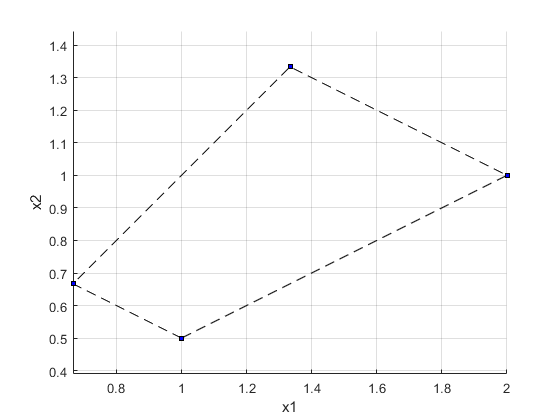

Число ориентиров = 4



[V, P1, P2, P3, P4] = EqnWeakR2(inf(A), sup(A), inf(h), sup(h));

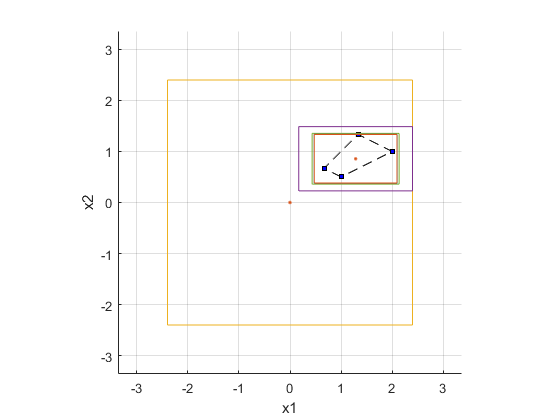

n = 20;
bar_list = [start_bar];
x = start_bar;
for i=1:n
    x = intersect(L * h + C * x, x);
    bar_list = [bar_list x];
end
plotintval(bar_list, 'n')
grid on

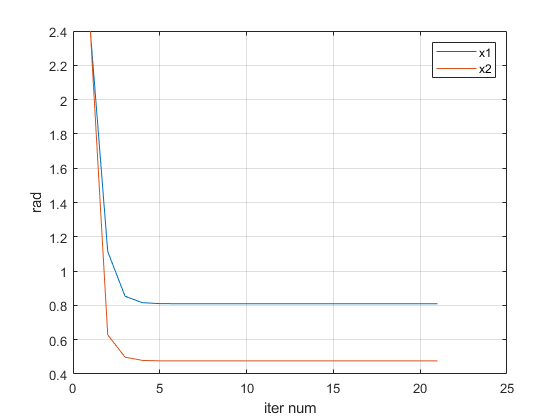

rads = zeros(2, size(bar_list, 2));
dest = zeros(1, size(bar_list, 2));
last_center = mid(bar_list(:, size(bar_list, 2)));
for i=1:size(bar_list, 2)
    rads(:, i) = rad(bar_list(:, i));
    dest(1, i) = norm(mid(bar_list(:, i)) - last_center);
end
figure
plot(rads(1, :))
hold on
plot(rads(2, :))
ylabel('rad')
xlabel('iter num')
legend('x1', 'x2')
grid on

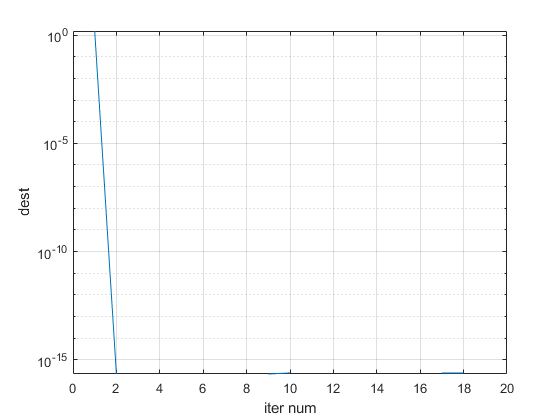

figure 
semilogy(dest)
ylabel('dest')
xlabel('iter num')
grid on

J = @(x) [a b; 1 / x(2), - x(1) ./ (x(2) * x(2))];
start_bar = [infsup(0.1, 5); infsup(0.1, 5)];
L = @(x) inv(mid(J(x)));
C = @(x) eye(2) - L(x) * J(x);
% модуль баженова = магнитуда, mag()
max(eig(mag(C(start_bar))))

ans = 1.9003

F = @(x) [a * x(1) + b * x(2) - c;x(1) ./ x(2) - k];
K = @(x) mid(x) - L(x) * F(mid(x)) - C(x) * (x - mid(x));

n = 200;
bar_list = [start_bar];
x = start_bar;
for i=1:n
    x = intersect(K(x), x);
    bar_list = [bar_list x];
end
figure
EqnWeakR2(inf(A), sup(A), inf(h), sup(h));

Число ориентиров = 4



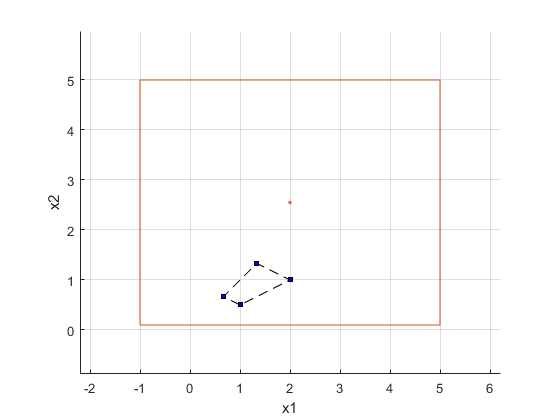

plotintval(bar_list, 'n')
grid on

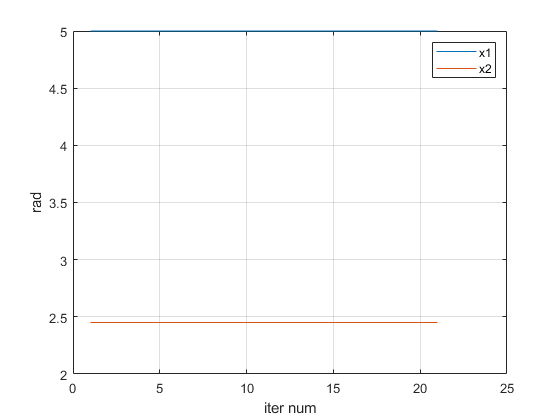

rads = zeros(2, size(bar_list, 2));
dest = zeros(1, size(bar_list, 2));
last_center = mid(bar_list(:, size(bar_list, 2)));
for i=1:size(bar_list, 2)
    rads(:, i) = rad(bar_list(:, i));
    dest(1, i) = norm(mid(bar_list(:, i)) - last_center);
end
figure
plot(rads(1, :))
hold on
plot(rads(2, :))
ylabel('rad')
xlabel('iter num')
legend('x1', 'x2')
grid on

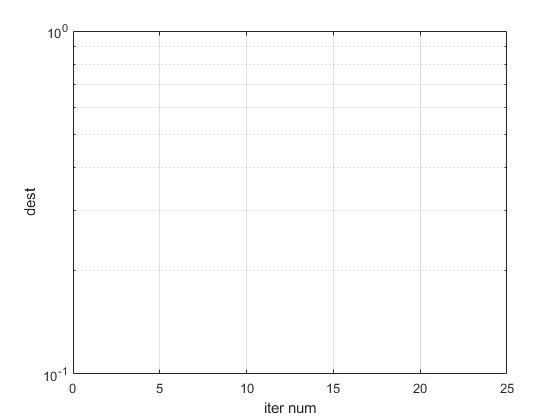

figure 
semilogy(dest)
ylabel('dest')
xlabel('iter num')
grid on